# ALL - ROBUSTNESS - MODEL UNCERTAINTY

## realvleospacecraft0UB

%models
loop_real = 'realvleospacecraft0UB_mpcpd';
loop_model = 'realvleospacecraft0_mpcpd_model';
sc_real = 'realvleospacecraft0UB';
sc_model = 'realvleospacecraft0_model';

open(loop_real);
set_param(loop_real, 'FastRestart', 'on',  'SaveState', 'on', 'StateSaveName', 'states', 'MaxStep', '1');
open(loop_model);
set_param(loop_model, 'FastRestart', 'on', 'SaveState', 'on', 'StateSaveName', 'states');

%params
t_tot = 200;
tar = 3;
costfunction = 1;

%disturbances
disturbances;

%mpcpd params
pred_horizon = 50;
cont_update = 10;
g = [1; 1; 1; 50; 50; 50];

### realvleospacecraft0

1_realvleospacecraft0UB_nodist_1

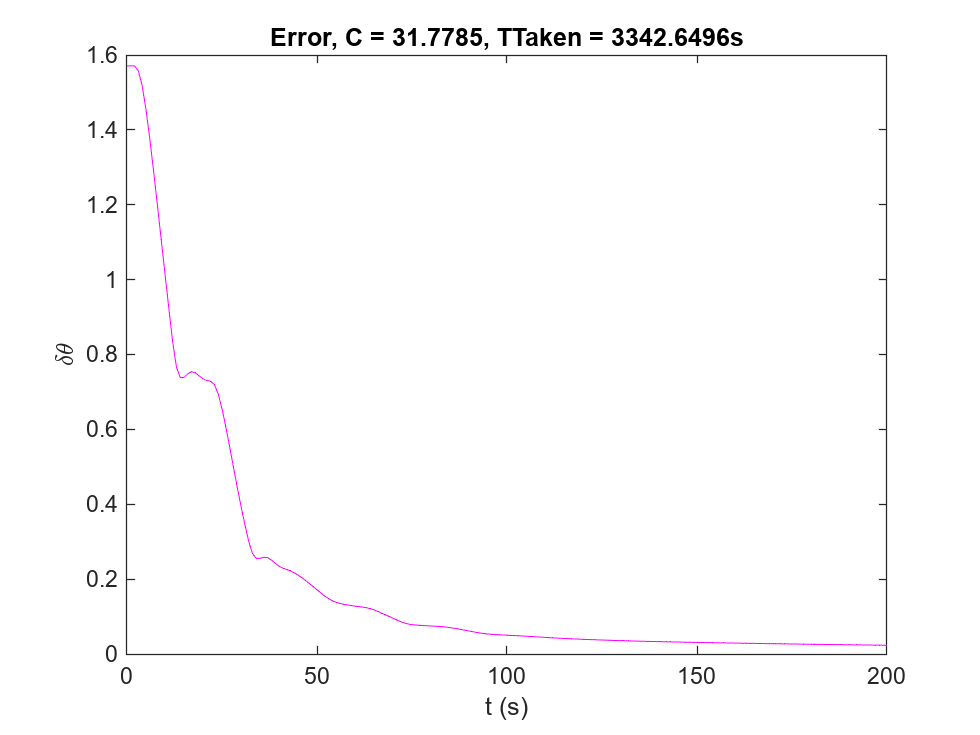

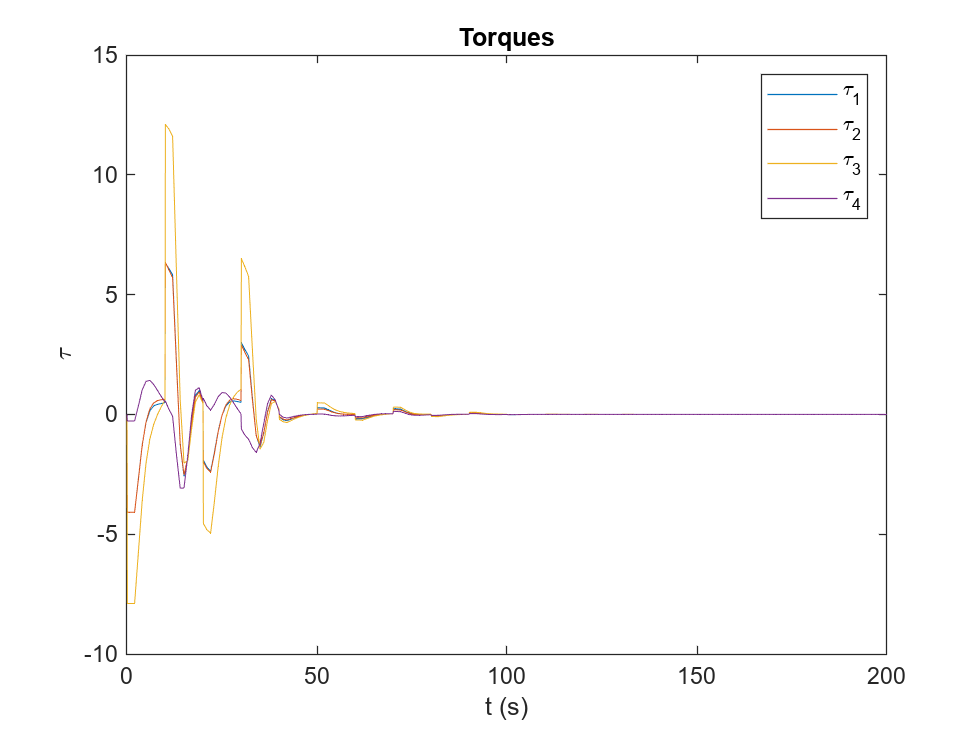

%info
filename = '1_realvleospacecraft0UB_nodist_1';
info = '1: 50 10 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 0.01k^2) with realvleospacecraft0 model';

%params
iterations = 25;
learning_rate = 0.1;

%disturbance
tau_dist_ser = no_tau_dist_ser;

%sim
simmpcpd;
prepvisualise;

%clean
close all;
clear;

## realvleospacecraft0LB

%models
loop_real = 'realvleospacecraft0LB_mpcpd';
loop_model = 'realvleospacecraft0_mpcpd_model';
sc_real = 'realvleospacecraft0LB';
sc_model = 'realvleospacecraft0_model';

open(loop_real);
set_param(loop_real, 'FastRestart', 'on',  'SaveState', 'on', 'StateSaveName', 'states', 'MaxStep', '1');
open(loop_model);
set_param(loop_model, 'FastRestart', 'on', 'SaveState', 'on', 'StateSaveName', 'states');

%params
t_tot = 200;
tar = 3;
costfunction = 1;

%disturbances
disturbances;

%mpcpd params
pred_horizon = 50;
cont_update = 10;
g = [1; 1; 1; 50; 50; 50];

### realvleospacecraft0

1_realvleospacecraft0LB_nodist_1

%info
filename = '1_realvleospacecraft0LB_nodist_1';
info = '1: 50 10 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 0.01k^2) with realvleospacecraft0 model';

%params
iterations = 25;
learning_rate = 0.1;

%disturbance
tau_dist_ser = no_tau_dist_ser;

%sim
simmpcpd;
prepvisualise;

%clean
close all;
clear;